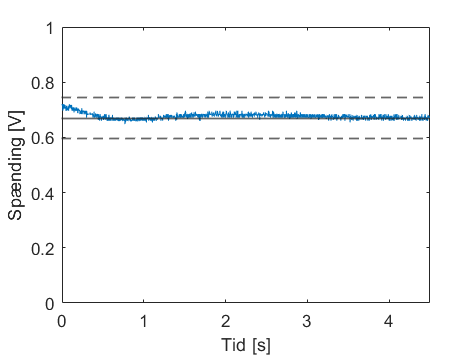

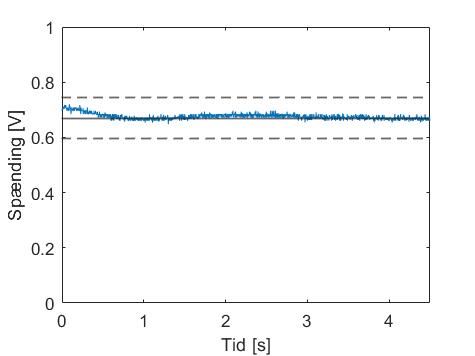

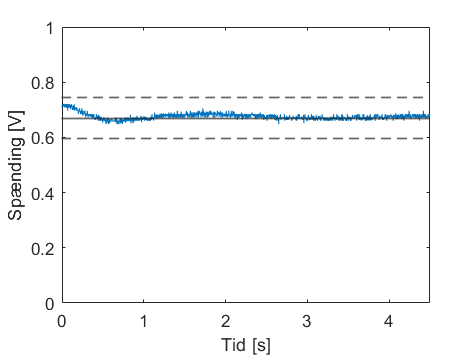

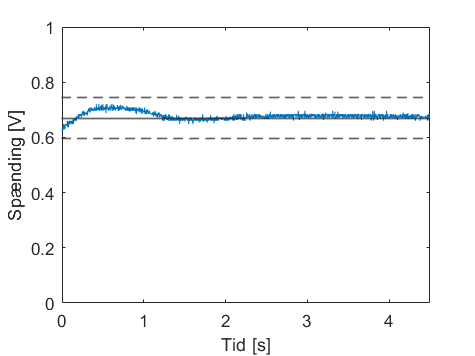

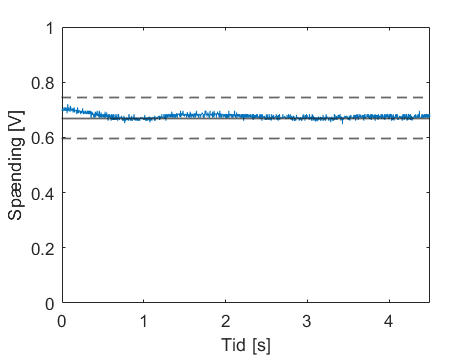

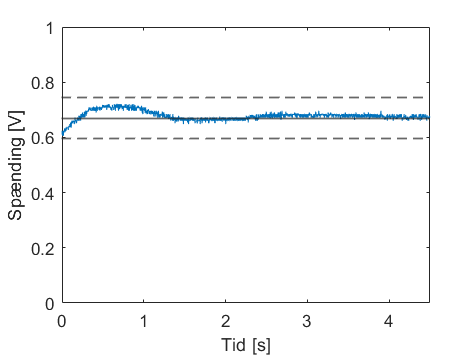

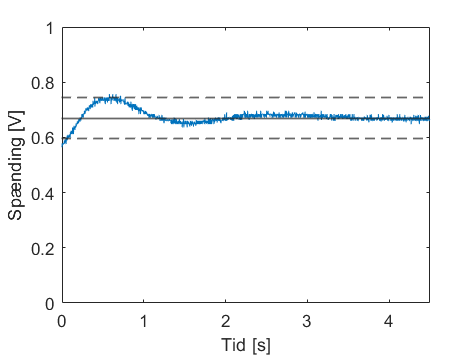

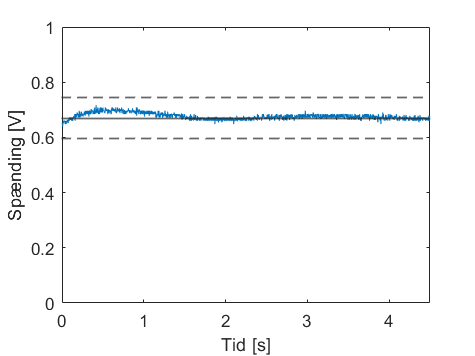

files = dir('*.csv');
for k = 1:length(files)
    if(files(k).name == "ref.csv")
        refMeas = readmatrix("ref.csv", 'NumHeaderLines',2);
        ref = refMeas(:,2);
        time = refMeas(:,1);
        middle = mean(ref);
        general = [middle, middle + middle*(5/45), middle - middle * (5/45)];
    else
        MeasData = readmatrix(files(k).name, NumHeaderLines=2);
        Meas = MeasData(:,2);
        figure(k+10);
        plotMeas(time, Meas, general)
        saveas(gcf,string(k),'epsc');
        outliers(k-1) = outsideInterval(time, Meas, general);
    end
end

outliers

outliers = 1×10 logical array
   0   0   0   0   0   0   1   0   0   0


## Funktioner

function plotMeas(t, meas, gen)
    plot(t, meas)
    yline(gen(1),'-', 'linewidth', 1)
    yline(gen(2:3), '--', 'linewidth', 1)
    xlabel('Tid [s]')
    ylabel('Spænding [V]')
    xlim([0 4.5])
    ylim([0 1])
end
function [outside] = outsideInterval(t, meas, gen)
    Val = find( meas>=gen(2) |  meas<=gen(3));
    tVal = t(max(Val));
    if tVal >= 0
        outside = true;
    else
        outside = false;
    end
end